%% Virtual signal for testing Q5-Q10 functions
% 這一大段是「虛擬產生 rx_frame」
% 目的：不用接 USRP，也可以先測試 Q5-Q10 的程式和 function 有沒有正常運作

clear; clc; close all;

FFT_size = 64;     % OFDM FFT 點數，也就是一個 OFDM symbol 的子載波數
cp_size = 16;      % Cyclic Prefix 長度
num_sym = 5;       % 模擬 5 個 OFDM data symbols

%% Used subcarriers
% 使用的子載波範圍：-26~-1 和 1~26
% 注意：0 subcarrier 通常是 DC，不拿來放資料
used_subc = [-26:-1 1:26];
data_subc = used_subc;

% fftshift 後的 index 對應：
% 子載波 -32 對應 index 1
% 子載波  0 對應 index 33
% 子載波 31 對應 index 64
data_idx = data_subc + FFT_size/2 + 1;

%% Generate known LTS in frequency domain
% 建立已知的 LTS frequency-domain pattern
% 接收端會用它和收到的 LTS 比較，進行 channel estimation
lts_f_known = zeros(FFT_size, 1);

% 在使用的子載波上放 BPSK 訊號：+1 或 -1
lts_f_known(data_idx) = 2*randi([0 1], length(data_idx), 1) - 1;

% 把 frequency-domain LTS 轉回 time-domain
% 傳送時真正送出去的是 time-domain 訊號
lts_t = ifft(ifftshift(lts_f_known));

%% Generate QPSK data symbols
% 產生 QPSK symbols，作為要傳送的 data
num_data = length(data_idx) * num_sym;

% I 路和 Q 路各自產生 +1 或 -1
bits_i = 2*randi([0 1], num_data, 1) - 1;
bits_q = 2*randi([0 1], num_data, 1) - 1;

% 組成 QPSK symbol，除以 sqrt(2) 是為了讓平均功率約為 1
tx_data_syms = (bits_i + 1j*bits_q) / sqrt(2);

%% Build OFDM data symbols
% 把 QPSK data 放到 OFDM 子載波上，然後 IFFT 變成 time-domain OFDM symbols
tx_data_time = [];

ptr = 1;   % 指向目前要放入 OFDM symbol 的 data 位置

for k = 1:num_sym
    % 建立一個 frequency-domain OFDM symbol
    X = zeros(FFT_size, 1);

    % 把 QPSK symbols 放到 data subcarriers 上
    X(data_idx) = tx_data_syms(ptr:ptr+length(data_idx)-1);
    ptr = ptr + length(data_idx);

    % IFFT：frequency domain -> time domain
    x_time = ifft(ifftshift(X));

    % 加上 cyclic prefix
    x_cp = [x_time(end-cp_size+1:end); x_time];

    % 串接所有 OFDM data symbols
    tx_data_time = [tx_data_time; x_cp];
end

%% Frame structure
% 建立完整 frame：
% front zero padding + LTS1 + LTS2 + data symbols + back zero padding

zero_pad_len = 100;

front_zero = zeros(zero_pad_len, 1);
back_zero  = zeros(zero_pad_len, 1);

% 第一個 LTS body 的起始位置
first_lts_start = zero_pad_len + 1;

% data symbols 的起始位置
% 因為前面有兩個 LTS，每個 LTS 長度是 FFT_size
data_start = first_lts_start + 2*FFT_size;

% 組成完整 transmit frame
tx_frame = [
    front_zero;
    lts_t;
    lts_t;
    tx_data_time;
    back_zero
];

%% Apply simple frequency-domain channel
% 建立一個簡單的 frequency-domain channel
% H_true 是我們模擬的真實通道
H_true = ones(FFT_size, 1);

% 讓使用中的子載波有一點不同的 magnitude 和 phase
% 這樣通道就不是完全平坦的，而是稍微 frequency selective
H_true(data_idx) = 0.8 + 0.3*rand(length(data_idx),1) ...
                 + 1j*(0.2*randn(length(data_idx),1));

% 初始化接收訊號
rx_frame = zeros(size(tx_frame));

%% Apply channel to 1st LTS
% 對第一個 LTS 套用通道：
% frequency-domain received = transmitted LTS * channel
rx_lts1_f = lts_f_known .* H_true;

% 轉回 time-domain，放入 rx_frame 對應位置
rx_lts1_t = ifft(ifftshift(rx_lts1_f));
rx_frame(first_lts_start:first_lts_start+FFT_size-1) = rx_lts1_t;

%% Apply channel to 2nd LTS
% 對第二個 LTS 套用相同通道
rx_lts2_f = lts_f_known .* H_true;
rx_lts2_t = ifft(ifftshift(rx_lts2_f));
rx_frame(first_lts_start+FFT_size:first_lts_start+2*FFT_size-1) = rx_lts2_t;

%% Apply channel to OFDM data symbols
% 對每一個 OFDM data symbol 套用 frequency-domain channel
sym_len = FFT_size + cp_size;

for k = 1:num_sym
    % 找出第 k 個 OFDM symbol 在 frame 裡的位置
    start_idx = data_start + (k-1)*sym_len;
    end_idx = start_idx + sym_len - 1;

    % 取出含 CP 的 OFDM symbol
    tx_sym_cp = tx_frame(start_idx:end_idx);

    % 移除 CP
    tx_sym_no_cp = tx_sym_cp(cp_size+1:end);

    % FFT：time domain -> frequency domain
    X = fftshift(fft(tx_sym_no_cp));

    % 通過通道：Y = X * H
    Y = X .* H_true;

    % IFFT 回 time domain
    y_time = ifft(ifftshift(Y));

    % 重新加回 CP
    y_cp = [y_time(end-cp_size+1:end); y_time];

    % 放入 rx_frame
    rx_frame(start_idx:end_idx) = y_cp;
end

%% Add AWGN noise
% 加入白雜訊，模擬真實接收訊號
SNR_dB = 25;

% 計算目前訊號平均功率
sig_pow = mean(abs(rx_frame).^2);

% 根據指定 SNR 算出雜訊功率
noise_pow = sig_pow / 10^(SNR_dB/10);

% 產生 complex Gaussian noise
noise = sqrt(noise_pow/2) * ...
    (randn(size(rx_frame)) + 1j*randn(size(rx_frame)));

% 接收訊號 = 通過通道後的訊號 + 雜訊
rx_frame = rx_frame + noise;

fprintf('Virtual rx_frame generated.\n');

Virtual rx_frame generated.


fprintf('length(rx_frame) = %d\n', length(rx_frame));

length(rx_frame) = 728


fprintf('first_lts_start = %d\n', first_lts_start);

first_lts_start = 101


fprintf('data_start      = %d\n', data_start);

data_start      = 229


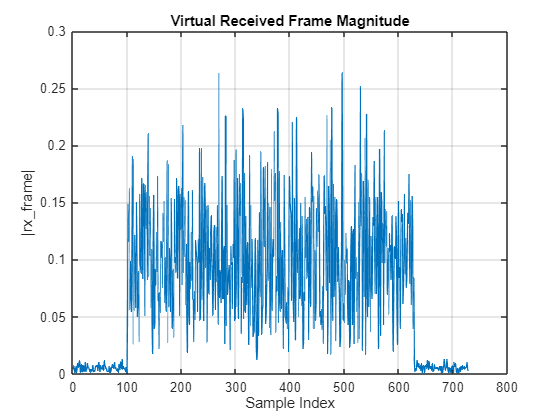


%% Quick plot
% 畫出整個虛擬接收 frame 的 magnitude
% 可以用來確認 LTS 和 data symbol 大概在哪裡
figure;
plot(abs(rx_frame), 'LineWidth', 1);
grid on;
title('Virtual Received Frame Magnitude');
xlabel('Sample Index');
ylabel('|rx\_frame|');

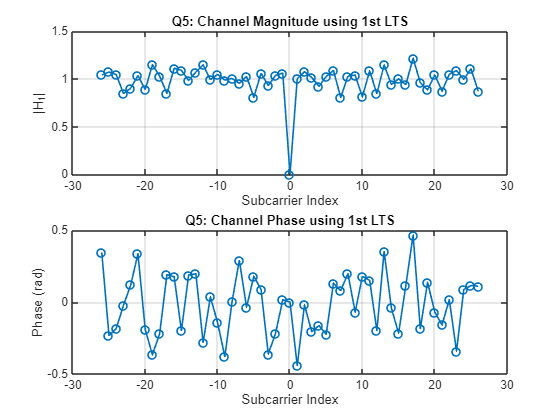



%% Q5-Q10
% 下面開始是正式測試 Q5-Q10 的部分
% 如果之後真的接 USRP，這些變數應該由前面題目或隊友提供：
% % rx_frame
% % first_lts_start
% data_start
% lts_f_known
% data_idx
% tx_data_syms


%% Q5
% 取出第一個 Long Training Symbol，並用它估測 channel

rx_lts_1 = extractLTS(rx_frame, first_lts_start, 1, FFT_size);
H1 = estimateChannelFromLTS(rx_lts_1, lts_f_known);

% 題目要求畫 subcarrier -26 到 26
% 這裡包含 0 subcarrier，但 DC 通常沒有資料，所以中間可能會是 0 或怪點
used_subc = -26:26;

% 將 subcarrier index 轉換成 fftshift 後的 MATLAB array index
idx = used_subc + FFT_size/2 + 1;

figure;

% 畫 channel magnitude
subplot(2,1,1);
plot(used_subc, abs(H1(idx)), '-o', 'LineWidth', 1.2);
grid on;
xlabel('Subcarrier Index');
ylabel('|H_1|');
title('Q5: Channel Magnitude using 1st LTS');

% 畫 channel phase
subplot(2,1,2);
plot(used_subc, angle(H1(idx)), '-o', 'LineWidth', 1.2);
grid on;
xlabel('Subcarrier Index');
ylabel('Phase (rad)');
title('Q5: Channel Phase using 1st LTS');

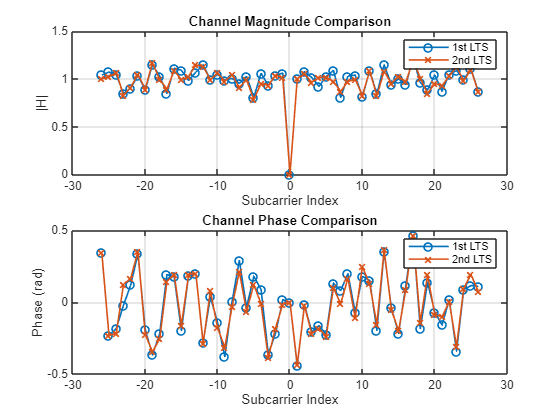



%% Q6
% 取出第二個 LTS，也做 channel estimation
% 然後比較 H1 和 H2 的 magnitude / phase 是否接近

rx_lts_2 = extractLTS(rx_frame, first_lts_start, 2, FFT_size);
H2 = estimateChannelFromLTS(rx_lts_2, lts_f_known);

% 畫出第一個 LTS 和第二個 LTS 估測到的 channel 比較
plotChannelCompare(H1, H2);

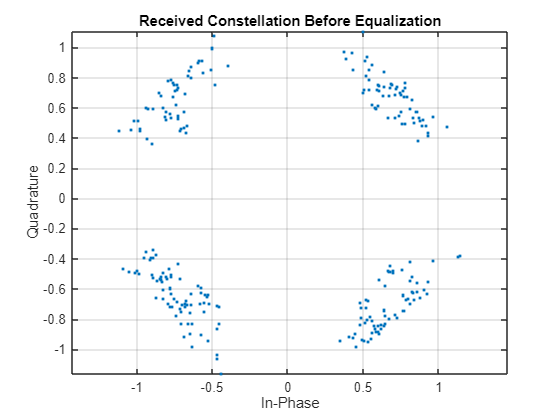



%% Q8
% 取出 data symbols，並在 equalization 前畫星座圖
% 此時因為還沒除掉 channel，所以星座圖可能會被旋轉、縮放或拉歪

num_sym = 5;

% 從 rx_frame 裡面取出 5 個 OFDM symbols，每個都包含 CP
rx_symbols = extractOFDMSymbols(rx_frame, data_start, FFT_size, cp_size, num_sym);

% 儲存 equalization 前的 data subcarriers
rx_data_before_eq = [];

for k = 1:num_sym
    % 對第 k 個 OFDM symbol 做 OFDM demodulation：
    % 移除 CP + FFT + fftshift
    Y = ofdmDemodSymbol(rx_symbols(:, k), FFT_size, cp_size);

    % 只取出 data subcarriers
    rx_data_before_eq = [rx_data_before_eq; Y(data_idx)];
end

% 畫 equalization 前的 constellation
plotConstellation(rx_data_before_eq, 'Received Constellation Before Equalization');

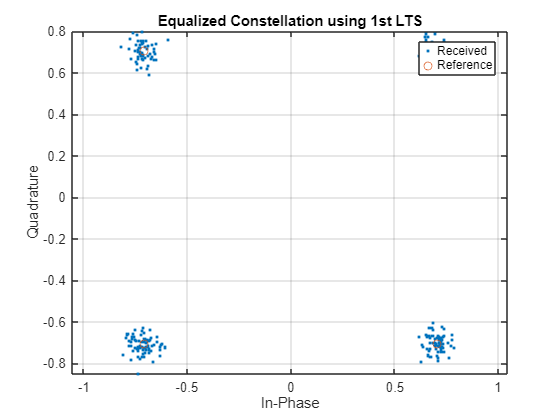



%% Q9
% 使用 Q5 和 Q6 估測出來的 channel 對 data symbols 做 equalization
% equalization 的概念：x_hat = Y / H

eq_data_1 = [];
eq_data_2 = [];

for k = 1:num_sym
    % OFDM demodulation
    Y = ofdmDemodSymbol(rx_symbols(:, k), FFT_size, cp_size);

    % 分別使用第一個 LTS 和第二個 LTS 的 channel estimate 做 equalization
    x_hat_1 = equalizeSymbol(Y, H1);
    x_hat_2 = equalizeSymbol(Y, H2);

    % 只取出 data subcarriers
    eq_data_1 = [eq_data_1; x_hat_1(data_idx)];
    eq_data_2 = [eq_data_2; x_hat_2(data_idx)];
end

% 畫 equalization 後的 constellation
% tx_data_syms(:) 是原本傳送的 QPSK reference symbols
plotConstellation(eq_data_1, 'Equalized Constellation using 1st LTS', tx_data_syms(:));

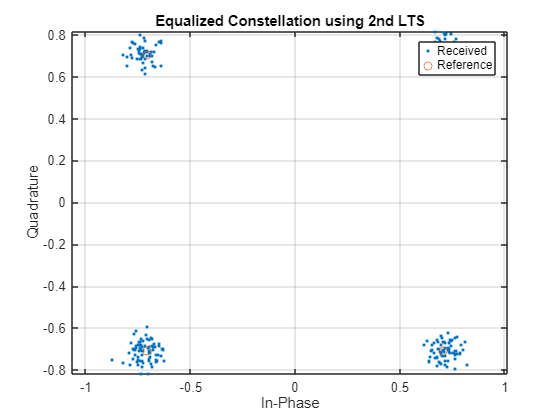

plotConstellation(eq_data_2, 'Equalized Constellation using 2nd LTS', tx_data_syms(:));



%% Q10
% 利用 zero padding 區域估計 noise power
% 利用 data symbol 區域估計 signal power
% 最後計算 SNR

num_sym = 5;

% 前面的 zero padding 區間
zero_pad_1 = [1, 100];

% 後面的 zero padding 區間
zero_pad_2 = [length(rx_frame)-99, length(rx_frame)];

% 計算 SNR
[snr_dB, sig_pow, noise_pow] = calcFrameSNR( ...
    rx_frame, data_start, FFT_size, cp_size, num_sym, zero_pad_1, zero_pad_2);

fprintf('Signal power = %.6f\n', sig_pow);

Signal power = 0.013117


fprintf('Noise power  = %.6f\n', noise_pow);

Noise power  = 0.000032


fprintf('SNR = %.3f dB\n', snr_dB);

SNR = 26.089 dB


function rx_lts = extractLTS(rx_frame, first_lts_start, which_lts, FFT_size)
% extractLTS
% 從 rx_frame 中取出指定的 Long Training Symbol。
%
% input:
% rx_frame        : 接收端完整 frame
% first_lts_start : 第一個 LTS body 的起始 index
% which_lts       : 要取第幾個 LTS，1 表示第一個，2 表示第二個
% FFT_size        : LTS 長度，通常等於 FFT size
%
% output:
% rx_lts          : 取出的 time-domain LTS，長度為 FFT_size

    if which_lts == 1
        start_idx = first_lts_start;
    elseif which_lts == 2
        start_idx = first_lts_start + FFT_size;
    else
        error('which_lts must be 1 or 2');
    end

    end_idx = start_idx + FFT_size - 1;

    if end_idx > length(rx_frame)
        error('LTS range exceeds rx_frame length');
    end

    rx_lts = rx_frame(start_idx:end_idx);
end


function H = estimateChannelFromLTS(rx_lts, lts_f_known)
% estimateChannelFromLTS
% 使用收到的 LTS 和已知的 LTS pattern 估測 channel。
%
% 原理：
% 頻域中接收訊號可以寫成
% Y = H * X
% 所以 channel estimate 為
% H = Y / X
%
% input:
% rx_lts      : time-domain received LTS
% lts_f_known : frequency-domain known LTS
%
% output:
% H           : frequency-domain channel estimate

    if length(rx_lts) ~= length(lts_f_known)
        error('rx_lts and lts_f_known must have the same length');
    end

    % 將收到的 LTS 轉到 frequency domain
    rx_lts_f = fftshift(fft(rx_lts));

    % 避免除以 0，只在 known LTS 非零的子載波上做 channel estimation
    H = zeros(size(rx_lts_f));
    valid_idx = abs(lts_f_known) > 1e-12;

    H(valid_idx) = rx_lts_f(valid_idx) ./ lts_f_known(valid_idx);
end


function rx_symbols = extractOFDMSymbols(rx_frame, data_start, FFT_size, cp_size, num_sym)
% extractOFDMSymbols
% 從 rx_frame 中取出多個 OFDM data symbols。
%
% 注意：這裡取出的每個 OFDM symbol 都「包含 CP」。
%
% input:
% rx_frame   : 接收端完整 frame
% data_start : 第一個 data OFDM symbol 的起始 index，包含 CP
% FFT_size   : FFT size
% cp_size    : cyclic prefix 長度
% num_sym    : 要取出的 OFDM symbol 數量
%
% output:
% rx_symbols : 每一欄是一個 OFDM symbol，大小為
%              (FFT_size + cp_size) x num_sym

    sym_len = FFT_size + cp_size;
    rx_symbols = zeros(sym_len, num_sym);

    for k = 1:num_sym
        start_idx = data_start + (k-1)*sym_len;
        end_idx   = start_idx + sym_len - 1;

        if end_idx > length(rx_frame)
            error('OFDM symbol range exceeds rx_frame length');
        end

        rx_symbols(:, k) = rx_frame(start_idx:end_idx);
    end
end


function Y = ofdmDemodSymbol(rx_symbol_with_cp, FFT_size, cp_size)
% ofdmDemodSymbol
% 對單一 OFDM symbol 做 demodulation。
%
% 步驟：
% 1. 移除 CP
% 2. 做 FFT
% 3. fftshift，讓子載波順序變成 -32 到 31
%
% input:
% rx_symbol_with_cp : 含 CP 的 time-domain OFDM symbol
% FFT_size          : FFT size
% cp_size           : cyclic prefix 長度
%
% output:
% Y                 : frequency-domain received OFDM symbol

    if length(rx_symbol_with_cp) ~= (FFT_size + cp_size)
        error('Input symbol length must be FFT_size + cp_size');
    end

    % 移除 cyclic prefix
    rx_no_cp = rx_symbol_with_cp(cp_size+1:end);

    % 轉到 frequency domain
    Y = fftshift(fft(rx_no_cp, FFT_size));
end


function x_hat = equalizeSymbol(Y, H)
% equalizeSymbol
% 使用 channel estimate 對 received OFDM symbol 做 equalization。
%
% 原理：
% Y = H * X
% 所以 X 的估計值為
% x_hat = Y / H
%
% input:
% Y : received frequency-domain OFDM symbol
% H : estimated channel
%
% output:
% x_hat : equalized frequency-domain symbol

    if length(Y) ~= length(H)
        error('Y and H must have the same length');
    end

    x_hat = zeros(size(Y));

    % 避免除以太小的 H，造成數值爆掉
    valid_idx = abs(H) > 1e-3;

    x_hat(valid_idx) = Y(valid_idx) ./ H(valid_idx);
end


function [snr_dB, sig_pow, noise_pow] = calcFrameSNR(rx_frame, data_start, FFT_size, cp_size, num_sym, zero_pad_1, zero_pad_2)
% calcFrameSNR
% 估計接收 frame 的 SNR。
%
% 方法：
% 1. data symbol 區域拿來估計 signal power
% 2. 前後 zero padding 區域拿來估計 noise power
% 3. SNR = 10 log10(signal power / noise power)
%
% input:
% rx_frame   : 接收端完整 frame
% data_start : data symbols 起始位置
% FFT_size   : FFT size
% cp_size    : cyclic prefix 長度
% num_sym    : data OFDM symbol 數量
% zero_pad_1 : 前面 zero padding 區間 [start, end]
% zero_pad_2 : 後面 zero padding 區間 [start, end]
%
% output:
% snr_dB     : SNR，單位 dB
% sig_pow    : signal power
% noise_pow  : noise power

    sym_len = FFT_size + cp_size;

    % data signal 區間
    sig_start = data_start;
    sig_end   = data_start + num_sym*sym_len - 1;

    if sig_end > length(rx_frame)
        error('Signal region exceeds rx_frame length');
    end

    if zero_pad_1(2) > length(rx_frame) || zero_pad_2(2) > length(rx_frame)
        error('Zero-padding region exceeds rx_frame length');
    end

    % 取出 signal region 和 noise region
    sig_region = rx_frame(sig_start:sig_end);
    noise_region = [rx_frame(zero_pad_1(1):zero_pad_1(2)); ...
                    rx_frame(zero_pad_2(1):zero_pad_2(2))];

    % 計算平均功率
    sig_pow = mean(abs(sig_region).^2);
    noise_pow = mean(abs(noise_region).^2);

    % 換成 dB
    snr_dB = 10 * log10(sig_pow / noise_pow);
end


function plotChannelCompare(H1, H2)
% plotChannelCompare
% 比較使用第一個 LTS 和第二個 LTS 估測出的 channel。
%
% 圖一：channel magnitude
% 圖二：channel phase
%
% 題目要求觀察 subcarrier -26 到 26。

    used_subc = -26:26;

    % fftshift 後 index 對應：
    % subcarrier 0 對應 index 33
    idx = used_subc + 33;

    figure;

    % 比較 magnitude
    subplot(2,1,1);
    plot(used_subc, abs(H1(idx)), '-o', 'LineWidth', 1.2); hold on;
    plot(used_subc, abs(H2(idx)), '-x', 'LineWidth', 1.2);
    xlabel('Subcarrier Index');
    ylabel('|H|');
    title('Channel Magnitude Comparison');
    legend('1st LTS', '2nd LTS');
    grid on;

    % 比較 phase
    subplot(2,1,2);
    plot(used_subc, angle(H1(idx)), '-o', 'LineWidth', 1.2); hold on;
    plot(used_subc, angle(H2(idx)), '-x', 'LineWidth', 1.2);
    xlabel('Subcarrier Index');
    ylabel('Phase (rad)');
    title('Channel Phase Comparison');
    legend('1st LTS', '2nd LTS');
    grid on;
end


function plotConstellation(sym, plot_title, ref_sym)
% plotConstellation
% 畫星座圖。
%
% input:
% sym        : 要畫的 received 或 equalized symbols
% plot_title : 圖的標題
% ref_sym    : optional，原本 transmitted symbols，可以拿來對照

    figure;

    % 畫 received / estimated symbols
    plot(real(sym), imag(sym), '.');
    hold on;

    % 如果有提供 reference symbols，就一起畫出來比較
    if nargin >= 3 && ~isempty(ref_sym)
        plot(real(ref_sym), imag(ref_sym), 'o');
        legend('Received', 'Reference');
    end

    xlabel('In-Phase');
    ylabel('Quadrature');
    title(plot_title);
    axis equal;
    grid on;
end